Task 0

I dont mind if the lecture is digital or physical, but I would really like if the lectures are recorded as the lecture collides with something else for me. I read the powerpoints but I dont feel like this is sufficent. 

And I think either the assignments should be out earlier or the assignment lecture should be moved to monday or tuesday, as the time from getting the assignment to the assignment lecture/aid is very short.

Loading in the files and setting global variables given in assignment.

invivo_data = load("invivoData.mat");
sim_data = load("simdata.mat");
c = 1540;

Task 1

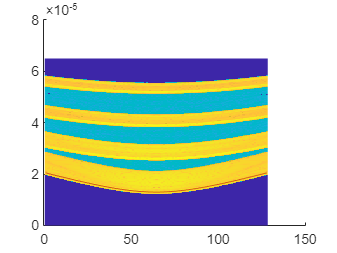

sim_elpos = sim_data.elPosX;
sim_Rf = sim_data.RFdata;
sim_Rf_t = sim_data.RF_t;
x1 = 0; 
z1 = 0.01; %meter
TOF_sim = TOF(z1,c,x1,sim_elpos);
[sim_rows, sim_cols] = size(sim_Rf);
sim_xaxis = linspace(1,sim_cols,sim_cols);
%colormap(gray(256));
%imagesc(sim_Rf');
figure(1);
imagesc('XData',sim_xaxis,'YData',sim_Rf_t,'CData', log(abs(sim_Rf)));
hold on;
plot(TOF_sim);


x = linspace( -2e-2, 2e-2, 256); %x-coordinates
zlen = 512;
z = linspace( 0, 4.5e-2, zlen).'; %z-coordinates
sim_elpos = permute(sim_elpos, [3 2 1]);
[X, Z] = meshgrid( x, z); %make X and Z matrices
% initialize TOF-matrix
%TOF_sim_0 = zeros( length(z), length(x), length(sim_elpos) );
TOF_sim_mat = TOF(z,c,x,sim_elpos);

Arrays have incompatible sizes for this operation.

Error in ass6_code>TOF (line 115)
    t_rx = (sqrt((x-elposx).^2 + z.^2))/c;

Related documentation


%TOF_sim_mat = permute(TOF_sim_mat,[3,2,1])



Task 2 

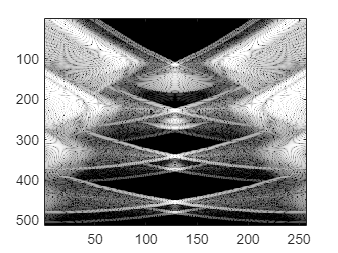

gain = -80;
dyn = 80; 
delayed_data = interpTOF(sim_Rf, sim_Rf_t, TOF_sim_mat);
bf_sim_rf = squeeze(sum(delayed_data,1));
figure(2), imagesc( 20*log10( abs( bf_sim_rf) ) )
caxis([-dyn 0]-gain);
colormap("gray");

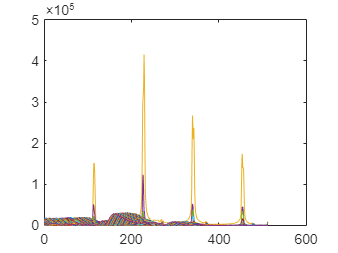

sim_envelope = abs(hilbert(bf_sim_rf)); 
figure(3);
plot(sim_envelope);

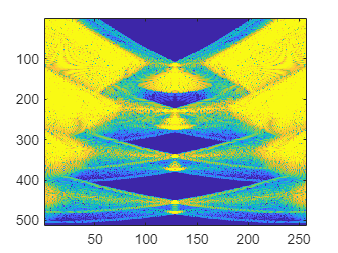

apod = hamming( size( delayed_data, 1) ); 
bf_sim_rf_apod1 = squeeze( sum( delayed_data.*apod) );
figure(4), imagesc( 20*log10( abs( bf_sim_rf_apod1) ) );
%colormap("gray");
dyn = 80;
gain = -60;
caxis([-dyn 0]-gain);

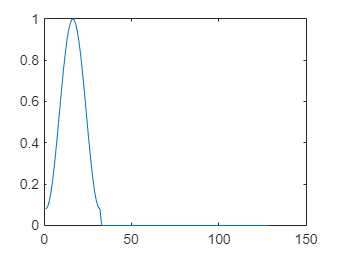


apod_32_first = zeros(size( delayed_data, 1),1);
apod_32_first(1:32) = hamming(32); %this didnt look right, 
% but didnt quite understand how it should be done
bf_sim_rf_apod2 = squeeze( sum( delayed_data.*apod_32_first) );
figure(5);
plot(apod_32_first)

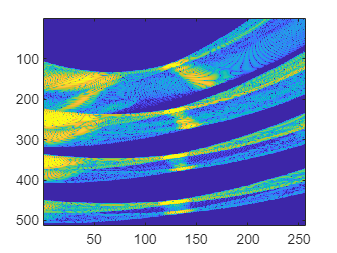

figure(6), imagesc( 20*log10( abs( bf_sim_rf_apod2) ) ); %dont know why 
% sometimes the color is blue and yellow and sometimes black and white.
dyn = 80;
gain = -60;
caxis([-dyn 0]-gain);

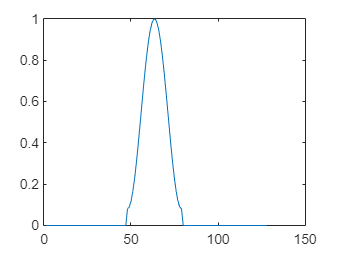


apod_32_center = zeros(size( delayed_data, 1),1);
apod_32_center(48:79) = hamming(32); %ich center
bf_sim_rf_apod3 = squeeze( sum( delayed_data.*apod_32_center) );
figure(7);
plot(apod_32_center)

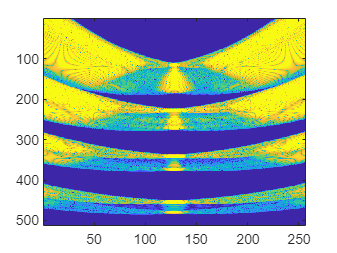

figure(8), imagesc( 20*log10( abs( bf_sim_rf_apod3) ) ); %dont know why 
% sometimes the color is blue and yellow and sometimes black and white.
dyn = 80;
gain = -60;
caxis([-dyn 0]-gain);

It seems like we are squeezing the image in different directions. And changing the size of the sidelobes.

Task 3

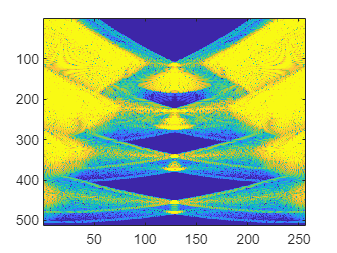

%for x = 0 amd fnumber = 1 
F = 1;
expand_apod = zeros(length(sim_elpos),length(z),length(x));
for i = 1:length(x)
    expand_apod(:,:,i) = generateApod(sim_elpos,x(i),z,F);
end
bf_sim_rf_expand_apod= squeeze( sum( delayed_data.*expand_apod) );

figure(10);
imagesc( 20*log10( abs( bf_sim_rf_expand_apod) ) );
dyn = 80;
gain = -60;
caxis([-dyn 0]-gain);

 %dont know why 
% sometimes the color is blue and yellow and sometimes black and white.

With high F# the sidelobes gets distorted.

Task 4

viv_elpos = invivo_data.elPosX;
viv_Rf = invivo_data.RFdata;
viv_Rf_t = invivo_data.RF_t;

[viv_rows, viv_cols] = size(viv_Rf);
viv_xaxis = linspace(1,viv_cols,viv_cols);

% x = linspace( -2e-2, 2e-2, 256); %x-coordinates
% zlen = 512;
% z = linspace( 0, 4.5e-2, zlen).'; %z-coordinates
% viv_elpos = permute(viv_elpos, [3 2 1]);
% [X, Z] = meshgrid( x, z); %make X and Z matrices
% % initialize TOF-matrix
% %TOF_sim_0 = zeros( length(z), length(x), length(sim_elpos) );
% TOF_viv = TOF(z,c,x,viv_elpos);

Arrays have incompatible sizes for this operation.

Error in ass6_code>TOF (line 115)
    t_rx = (sqrt((x-elposx).^2 + z.^2))/c;

Related documentation

% delayed_data_viv = interpTOF(viv_Rf, viv_Rf_t, TOF_viv);
% 
% F = 1;
% expand_apod_viv = zeros(length(viv_elpos),length(z),length(x));
% for i = 1:length(x)
%     expand_apod(:,:,i) = generateApod(viv_elpos,x(i),z,F);
% end
% bf_sim_rf_expand_apod= squeeze( sum( delayed_data.*expand_apod_viv) );
% 
% bf_viv_rf_ea = squeeze(sum(delayed_data_viv.*exp_viv));
% figure(11), imagesc( 20*log10( abs( bf_viv_rf_ea) ) );
% caxis([-dyn 0]-gain);

%dont know why the tof didnt work now, this worked yesterday but when i
%tried today i get incompatible shapes

Functions

function t = TOF(z,c,x,elposx)
    t_tx = z/c;
    t_rx = (sqrt((x-elposx).^2 + z.^2))/c;
    t = t_tx+t_rx;
end